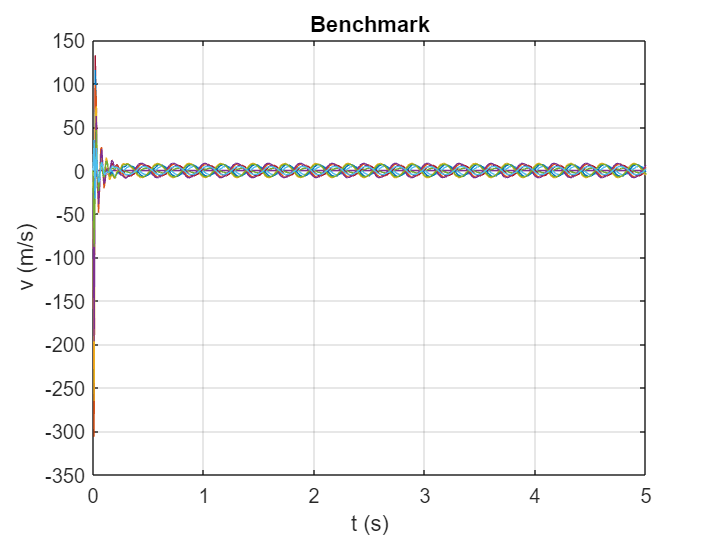

Cint = ext.tether.Cint;        % Internal damping
Cn = ext.tether.Cn;            % Normal drag coefficient
Ct = ext.tether.Ct;            % Tangential drag coefficient
E = ext.tether.E;              % Youngs modulus
dt = ext.tether.d;             % Tether diameter
l = ext.tether.init.lt;             % Tether length
l0 = ext.tether.init.lu;       % Length of each segment

% Ocean currents (m/s)
Ucx = 0;
Ucy = 0;
Ucz = 0;

% Position and velocity of base node
rx_1 = 0;
ry_1 = 0;
rz_1 = 0;
rxd_1 = 0;
ryd_1 = 0;
rzd_1 = 0;

%% Position and velocity of remaining nodes
% Position 
rx_2 = 0;
rx_3 = 0;
rx_4 = 0;
rx_5 = 0;
rx_6 = 0;
rx_7 = 0;
rx_8 = 0;
rx_9 = 0;
rx_10 = 0;
rx_11 = 0;
ry_2 = 0;
ry_3 = 0;
ry_4 = 0;
ry_5 = 0;
ry_6 = 0;
ry_7 = 0;
ry_8 = 0;
ry_9 = 0;
ry_10 = 0;
ry_11 = 0;
rz_2 = rz_1 + l0;
rz_3 = rz_2 + l0;
rz_4 = rz_3 + l0;
rz_5 = rz_4 + l0;
rz_6 = rz_5 + l0;
rz_7 = rz_6 + l0;
rz_8 = rz_7 + l0;
rz_9 = rz_8 + l0;
rz_10 = rz_9 + l0;
rz_11 = 25;

% Velocity
rxd_2 = 0;
rxd_3 = 0;
rxd_4 = 0;
rxd_5 = 0;
rxd_6 = 0;
rxd_7 = 0;
rxd_8 = 0;
rxd_9 = 0;
rxd_10 = 0;
ryd_2 = 0;
ryd_3 = 0;
ryd_4 = 0;
ryd_5 = 0;
ryd_6 = 0;
ryd_7 = 0;
ryd_8 = 0;
ryd_9 = 0;
ryd_10 = 0;
rzd_2 = 0;
rzd_3 = 0;
rzd_4 = 0;
rzd_5 = 0;
rzd_6 = 0;
rzd_7 = 0;
rzd_8 = 0;
rzd_9 = 0;
rzd_10 = 0;
X = zeros(1,54);
X(:,1:27) = [rx_2,rx_3,rx_4,rx_5,rx_6,rx_7,rx_8,rx_9,rx_10,ry_2,ry_3,ry_4,ry_5,ry_6,ry_7,ry_8,ry_9,ry_10,rz_2,rz_3,rz_4,rz_5,rz_6,rz_7,rz_8,rz_9,rz_10];
X(:,28:54) = [rxd_2,rxd_3,rxd_4,rxd_5,rxd_6,rxd_7,rxd_8,rxd_9,rxd_10,ryd_2,ryd_3,ryd_4,ryd_5,ryd_6,ryd_7,ryd_8,ryd_9,ryd_10,rzd_2,rzd_3,rzd_4,rzd_5,rzd_6,rzd_7,rzd_8,rzd_9,rzd_10];
x = reshape(X,[],1);
tspan = 0:0.01:5;
x0 =x;
[t,xD] = ode45(@(t,x) Tether(t,Cint,Cn,Ct,E,Ucx,Ucx,Ucx,Ucx,Ucx,Ucx,Ucx,Ucx,Ucx,Ucx,Ucy,Ucy,Ucy,Ucy,Ucy,Ucy,Ucy,Ucy,Ucy,Ucy,Ucz,Ucz,Ucz,Ucz,Ucz,Ucz,Ucz,Ucz,Ucz,Ucz,dt,l,rx_1,ry_1,rz_1,rxd_1,ryd_1,rzd_1,rx_11,ry_11,rz_11,x),tspan,x0);

figure
plot(tspan,xD(:,28:54))
grid on
xlabel("t (s)")
ylabel("v (m/s)")
title("Benchmark")


tspan = 0:0.01:5;
x0 = ics.tether.xstate;
[t,x] = ode45(@(t,x) pDD(t,x,ext,phy),tspan,x0);
error = max(abs(xD(:,46)-x(:,30)))

error = 51.9630

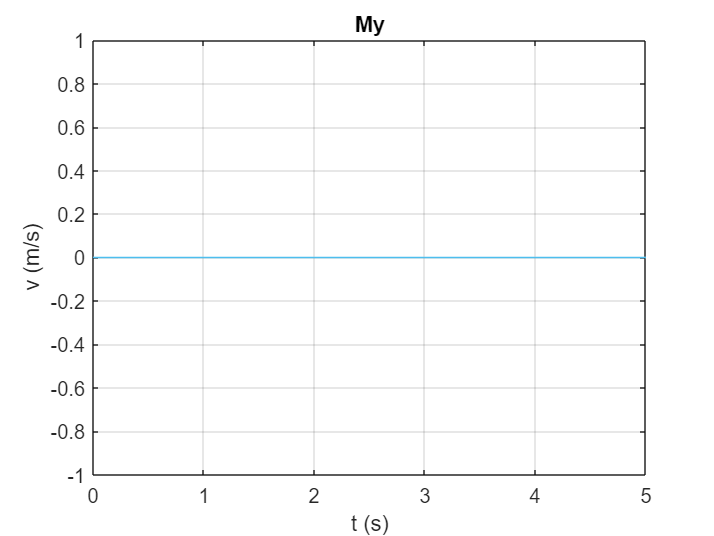

plot(tspan,x(:,28:54))
grid on
xlabel('t (s)')
ylabel ('v (m/s)')
title("My")

function xd = Tether(t,C_d_t,Cd_t,Ct_t,E,Ucx_1,Ucx_2,Ucx_3,Ucx_4,Ucx_5,Ucx_6,Ucx_7,Ucx_8,Ucx_9,Ucx_10,Ucy_1,Ucy_2,Ucy_3,Ucy_4,Ucy_5,Ucy_6,Ucy_7,Ucy_8,Ucy_9,Ucy_10,Ucz_1,Ucz_2,Ucz_3,Ucz_4,Ucz_5,Ucz_6,Ucz_7,Ucz_8,Ucz_9,Ucz_10,d_t,l,rx_1,ry_1,rz_1,rxd_1,ryd_1,rzd_1,rx_11,ry_11,rz_11,x)


%    This function was generated by the Symbolic Math Toolbox version 8.6.
%    17-Mar-2022 13:31:39
%if simtime > 0.5
rx_2 = x(1);
rx_3 = x(2);
rx_4 = x(3);
rx_5 = x(4);
rx_6 = x(5);
rx_7 = x(6);
rx_8 = x(7);
rx_9 = x(8);
rx_10 = x(9);
ry_2 = x(10);
ry_3 = x(11);
ry_4 = x(12);
ry_5 = x(13);
ry_6 = x(14);
ry_7 = x(15);
ry_8 = x(16);
ry_9 = x(17);
ry_10 = x(18);
rz_2 = x(19);
rz_3 = x(20);
rz_4 = x(21);
rz_5 = x(22);
rz_6 = x(23);
rz_7 = x(24);
rz_8 = x(25);
rz_9 = x(26);
rz_10 = x(27);
rxd_2 = x(28);
rxd_3 = x(29);
rxd_4 = x(30);
rxd_5 = x(31);
rxd_6 = x(32);
rxd_7 = x(33);
rxd_8 = x(34);
rxd_9 = x(35);
rxd_10 = x(36);
ryd_2 = x(37);
ryd_3 = x(38);
ryd_4 = x(39);
ryd_5 = x(40);
ryd_6 = x(41);
ryd_7 = x(42);
ryd_8 = x(43);
ryd_9 = x(44);
ryd_10 = x(45);
rzd_2 = x(46);
rzd_3 = x(47);
rzd_4 = x(48);
rzd_5 = x(49);
rzd_6 = x(50);
rzd_7 = x(51);
rzd_8 = x(52);
rzd_9 = x(53);
rzd_10 = x(54);

t2 = d_t.^2;
t3 = -Ucx_2;
t4 = -Ucx_3;
t5 = -Ucx_4;
t6 = -Ucx_5;
t7 = -Ucx_6;
t8 = -Ucx_7;
t9 = -Ucx_8;
t10 = -Ucx_9;
t11 = -Ucx_10;
t12 = -Ucy_2;
t13 = -Ucy_3;
t14 = -Ucy_4;
t15 = -Ucy_5;
t16 = -Ucy_6;
t17 = -Ucy_7;
t18 = -Ucy_8;
t19 = -Ucy_9;
t20 = -Ucy_10;
t21 = -Ucz_2;
t22 = -Ucz_3;
t23 = -Ucz_4;
t24 = -Ucz_5;
t25 = -Ucz_6;
t26 = -Ucz_7;
t27 = -Ucz_8;
t28 = -Ucz_9;
t29 = -Ucz_10;
t30 = 1.0./l;
t31 = -rx_2;
t32 = -rx_3;
t33 = -rx_4;
t34 = -rx_5;
t35 = -rx_6;
t36 = -rx_7;
t37 = -rx_8;
t38 = -rx_9;
t39 = -rx_10;
t40 = -rx_11;
t41 = -rxd_2;
t42 = -rxd_3;
t43 = -rxd_4;
t44 = -rxd_5;
t45 = -rxd_6;
t46 = -rxd_7;
t47 = -rxd_8;
t48 = -rxd_9;
t49 = -rxd_10;
t50 = -ry_2;
t51 = -ry_3;
t52 = -ry_4;
t53 = -ry_5;
t54 = -ry_6;
t55 = -ry_7;
t56 = -ry_8;
t57 = -ry_9;
t58 = -ry_10;
t59 = -ry_11;
t60 = -ryd_2;
t61 = -ryd_3;
t62 = -ryd_4;
t63 = -ryd_5;
t64 = -ryd_6;
t65 = -ryd_7;
t66 = -ryd_8;
t67 = -ryd_9;
t68 = -ryd_10;
t69 = -rz_2;
t70 = -rz_3;
t71 = -rz_4;
t72 = -rz_5;
t73 = -rz_6;
t74 = -rz_7;
t75 = -rz_8;
t76 = -rz_9;
t77 = -rz_10;
t78 = -rz_11;
t79 = -rzd_2;
t80 = -rzd_3;
t81 = -rzd_4;
t82 = -rzd_5;
t83 = -rzd_6;
t84 = -rzd_7;
t85 = -rzd_8;
t86 = -rzd_9;
t87 = -rzd_10;
t260 = l.*4.3e-3;
t88 = Ucx_2+t41;
t89 = Ucx_3+t42;
t90 = Ucx_4+t43;
t91 = Ucx_5+t44;
t92 = Ucx_6+t45;
t93 = Ucx_7+t46;
t94 = Ucx_8+t47;
t95 = Ucx_9+t48;
t96 = Ucx_10+t49;
t97 = Ucy_2+t60;
t98 = Ucy_3+t61;
t99 = Ucy_4+t62;
t100 = Ucy_5+t63;
t101 = Ucy_6+t64;
t102 = Ucy_7+t65;
t103 = Ucy_8+t66;
t104 = Ucy_9+t67;
t105 = Ucy_10+t68;
t106 = Ucz_2+t79;
t107 = Ucz_3+t80;
t108 = Ucz_4+t81;
t109 = Ucz_5+t82;
t110 = Ucz_6+t83;
t111 = Ucz_7+t84;
t112 = Ucz_8+t85;
t113 = Ucz_9+t86;
t114 = Ucz_10+t87;
t115 = rx_1+t31;
t116 = rx_2+t32;
t117 = rx_3+t33;
t118 = rx_4+t34;
t119 = rx_5+t35;
t120 = rx_6+t36;
t121 = rx_7+t37;
t122 = rx_8+t38;
t123 = rx_9+t39;
t124 = rx_10+t40;
t125 = rxd_1+t41;
t126 = rxd_2+t42;
t127 = rxd_3+t43;
t128 = rxd_4+t44;
t129 = rxd_5+t45;
t130 = rxd_6+t46;
t131 = rxd_7+t47;
t132 = rxd_8+t48;
t133 = rxd_9+t49;
t134 = ry_1+t50;
t135 = ry_2+t51;
t136 = ry_3+t52;
t137 = ry_4+t53;
t138 = ry_5+t54;
t139 = ry_6+t55;
t140 = ry_7+t56;
t141 = ry_8+t57;
t142 = ry_9+t58;
t143 = ry_10+t59;
t144 = ryd_1+t60;
t145 = ryd_2+t61;
t146 = ryd_3+t62;
t147 = ryd_4+t63;
t148 = ryd_5+t64;
t149 = ryd_6+t65;
t150 = ryd_7+t66;
t151 = ryd_8+t67;
t152 = ryd_9+t68;
t153 = rz_1+t69;
t154 = rz_2+t70;
t155 = rz_3+t71;
t156 = rz_4+t72;
t157 = rz_5+t73;
t158 = rz_6+t74;
t159 = rz_7+t75;
t160 = rz_8+t76;
t161 = rz_9+t77;
t162 = rz_10+t78;
t163 = rzd_1+t79;
t164 = rzd_2+t80;
t165 = rzd_3+t81;
t166 = rzd_4+t82;
t167 = rzd_5+t83;
t168 = rzd_6+t84;
t169 = rzd_7+t85;
t170 = rzd_8+t86;
t171 = rzd_9+t87;
t229 = l.*t2.*pi.*2.5e+1;
t172 = abs(t115);
t173 = abs(t116);
t174 = abs(t117);
t175 = abs(t118);
t176 = abs(t119);
t177 = abs(t120);
t178 = abs(t121);
t179 = abs(t122);
t180 = abs(t123);
t181 = abs(t124);
t182 = abs(t134);
t183 = abs(t135);
t184 = abs(t136);
t185 = abs(t137);
t186 = abs(t138);
t187 = abs(t139);
t188 = abs(t140);
t189 = abs(t141);
t190 = abs(t142);
t191 = abs(t143);
t192 = abs(t153);
t193 = abs(t154);
t194 = abs(t155);
t195 = abs(t156);
t196 = abs(t157);
t197 = abs(t158);
t198 = abs(t159);
t199 = abs(t160);
t200 = abs(t161);
t201 = abs(t162);
t202 = t115.^2;
t203 = t116.^2;
t204 = t117.^2;
t205 = t118.^2;
t206 = t119.^2;
t207 = t120.^2;
t208 = t121.^2;
t209 = t122.^2;
t210 = t123.^2;
t211 = t134.^2;
t212 = t135.^2;
t213 = t136.^2;
t214 = t137.^2;
t215 = t138.^2;
t216 = t139.^2;
t217 = t140.^2;
t218 = t141.^2;
t219 = t142.^2;
t220 = t153.^2;
t221 = t154.^2;
t222 = t155.^2;
t223 = t156.^2;
t224 = t157.^2;
t225 = t158.^2;
t226 = t159.^2;
t227 = t160.^2;
t228 = t161.^2;
t261 = rxd_1.*t30.*t115.*1.0e+1;
t262 = ryd_1.*t30.*t134.*1.0e+1;
t263 = rzd_1.*t30.*t153.*1.0e+1;
t264 = t229+t260;
t265 = t30.*t116.*t125.*1.0e+1;
t266 = t30.*t117.*t126.*1.0e+1;
t267 = t30.*t118.*t127.*1.0e+1;
t268 = t30.*t119.*t128.*1.0e+1;
t269 = t30.*t120.*t129.*1.0e+1;
t270 = t30.*t121.*t130.*1.0e+1;
t271 = t30.*t122.*t131.*1.0e+1;
t272 = t30.*t123.*t132.*1.0e+1;
t273 = t30.*t124.*t133.*1.0e+1;
t274 = t30.*t135.*t144.*1.0e+1;
t275 = t30.*t136.*t145.*1.0e+1;
t276 = t30.*t137.*t146.*1.0e+1;
t277 = t30.*t138.*t147.*1.0e+1;
t278 = t30.*t139.*t148.*1.0e+1;
t279 = t30.*t140.*t149.*1.0e+1;
t280 = t30.*t141.*t150.*1.0e+1;
t281 = t30.*t142.*t151.*1.0e+1;
t282 = t30.*t143.*t152.*1.0e+1;
t283 = t30.*t154.*t163.*1.0e+1;
t284 = t30.*t155.*t164.*1.0e+1;
t285 = t30.*t156.*t165.*1.0e+1;
t286 = t30.*t157.*t166.*1.0e+1;
t287 = t30.*t158.*t167.*1.0e+1;
t288 = t30.*t159.*t168.*1.0e+1;
t289 = t30.*t160.*t169.*1.0e+1;
t290 = t30.*t161.*t170.*1.0e+1;
t291 = t30.*t162.*t171.*1.0e+1;
t230 = t172.^2;
t231 = t173.^2;
t232 = t174.^2;
t233 = t175.^2;
t234 = t176.^2;
t235 = t177.^2;
t236 = t178.^2;
t237 = t179.^2;
t238 = t180.^2;
t239 = t181.^2;
t240 = t182.^2;
t241 = t183.^2;
t242 = t184.^2;
t243 = t185.^2;
t244 = t186.^2;
t245 = t187.^2;
t246 = t188.^2;
t247 = t189.^2;
t248 = t190.^2;
t249 = t191.^2;
t250 = t192.^2;
t251 = t193.^2;
t252 = t194.^2;
t253 = t195.^2;
t254 = t196.^2;
t255 = t197.^2;
t256 = t198.^2;
t257 = t199.^2;
t258 = t200.^2;
t259 = t201.^2;
t292 = 1.0./t264;
t363 = t261+t262+t263;
t415 = t265+t274+t283;
t416 = t266+t275+t284;
t417 = t267+t276+t285;
t418 = t268+t277+t286;
t419 = t269+t278+t287;
t420 = t270+t279+t288;
t421 = t271+t280+t289;
t422 = t272+t281+t290;
t423 = t273+t282+t291;
t293 = t230+t240+t250;
t294 = t231+t241+t251;
t295 = t232+t242+t252;
t296 = t233+t243+t253;
t297 = t234+t244+t254;
t298 = t235+t245+t255;
t299 = t236+t246+t256;
t300 = t237+t247+t257;
t301 = t238+t248+t258;
t302 = t239+t249+t259;
t303 = 1.0./t293;
t304 = 1.0./t294;
t306 = 1.0./t295;
t308 = 1.0./t296;
t310 = 1.0./t297;
t312 = 1.0./t298;
t314 = 1.0./t299;
t316 = 1.0./t300;
t318 = 1.0./t301;
t320 = 1.0./t302.^2;
t321 = sqrt(t294);
t322 = sqrt(t295);
t323 = sqrt(t296);
t324 = sqrt(t297);
t325 = sqrt(t298);
t326 = sqrt(t299);
t327 = sqrt(t300);
t328 = sqrt(t301);
t329 = sqrt(t302);
t330 = 1.0./sqrt(t293);
t305 = t304.^2;
t307 = t306.^2;
t309 = t308.^2;
t311 = t310.^2;
t313 = t312.^2;
t315 = t314.^2;
t317 = t316.^2;
t319 = t318.^2;
t331 = 1.0./t321;
t332 = 1.0./t322;
t333 = 1.0./t323;
t334 = 1.0./t324;
t335 = 1.0./t325;
t336 = 1.0./t326;
t337 = 1.0./t327;
t338 = 1.0./t328;
t339 = 1.0./t329;
t340 = (l.*t330)./1.0e+1;
t350 = Ucx_1.*t202.*t303;
t351 = Ucy_1.*t211.*t303;
t352 = Ucz_1.*t220.*t303;
t364 = t88.*t203.*t304;
t365 = t89.*t204.*t306;
t366 = t90.*t205.*t308;
t367 = t91.*t206.*t310;
t368 = t92.*t207.*t312;
t369 = t93.*t208.*t314;
t370 = t94.*t209.*t316;
t371 = t95.*t210.*t318;
t372 = t97.*t212.*t304;
t373 = t98.*t213.*t306;
t374 = t99.*t214.*t308;
t375 = t100.*t215.*t310;
t376 = t101.*t216.*t312;
t377 = t102.*t217.*t314;
t378 = t103.*t218.*t316;
t379 = t104.*t219.*t318;
t380 = t106.*t221.*t304;
t381 = t107.*t222.*t306;
t382 = t108.*t223.*t308;
t383 = t109.*t224.*t310;
t384 = t110.*t225.*t312;
t385 = t111.*t226.*t314;
t386 = t112.*t227.*t316;
t387 = t113.*t228.*t318;
t341 = (l.*t331)./1.0e+1;
t342 = (l.*t332)./1.0e+1;
t343 = (l.*t333)./1.0e+1;
t344 = (l.*t334)./1.0e+1;
t345 = (l.*t335)./1.0e+1;
t346 = (l.*t336)./1.0e+1;
t347 = (l.*t337)./1.0e+1;
t348 = (l.*t338)./1.0e+1;
t349 = (l.*t339)./1.0e+1;
t353 = t340-1.0;
t388 = rxd_2+t3+t350;
t389 = ryd_2+t12+t351;
t390 = rzd_2+t21+t352;
t391 = rxd_3+t4+t364;
t392 = rxd_4+t5+t365;
t393 = rxd_5+t6+t366;
t394 = rxd_6+t7+t367;
t395 = rxd_7+t8+t368;
t396 = rxd_8+t9+t369;
t397 = rxd_9+t10+t370;
t398 = rxd_10+t11+t371;
t399 = ryd_3+t13+t372;
t400 = ryd_4+t14+t373;
t401 = ryd_5+t15+t374;
t402 = ryd_6+t16+t375;
t403 = ryd_7+t17+t376;
t404 = ryd_8+t18+t377;
t405 = ryd_9+t19+t378;
t406 = ryd_10+t20+t379;
t407 = rzd_3+t22+t380;
t408 = rzd_4+t23+t381;
t409 = rzd_5+t24+t382;
t410 = rzd_6+t25+t383;
t411 = rzd_7+t26+t384;
t412 = rzd_8+t27+t385;
t413 = rzd_9+t28+t386;
t414 = rzd_10+t29+t387;
t451 = C_d_t.*t116.*t331.*t415;
t452 = C_d_t.*t117.*t332.*t416;
t453 = C_d_t.*t118.*t333.*t417;
t454 = C_d_t.*t119.*t334.*t418;
t455 = C_d_t.*t120.*t335.*t419;
t456 = C_d_t.*t121.*t336.*t420;
t457 = C_d_t.*t122.*t337.*t421;
t458 = C_d_t.*t123.*t338.*t422;
t459 = C_d_t.*t135.*t331.*t415;
t460 = C_d_t.*t136.*t332.*t416;
t461 = C_d_t.*t137.*t333.*t417;
t462 = C_d_t.*t138.*t334.*t418;
t463 = C_d_t.*t139.*t335.*t419;
t464 = C_d_t.*t140.*t336.*t420;
t465 = C_d_t.*t141.*t337.*t421;
t466 = C_d_t.*t142.*t338.*t422;
t467 = C_d_t.*t154.*t331.*t415;
t468 = C_d_t.*t155.*t332.*t416;
t469 = C_d_t.*t156.*t333.*t417;
t470 = C_d_t.*t157.*t334.*t418;
t471 = C_d_t.*t158.*t335.*t419;
t472 = C_d_t.*t159.*t336.*t420;
t473 = C_d_t.*t160.*t337.*t421;
t474 = C_d_t.*t161.*t338.*t422;
t354 = t341-1.0;
t355 = t342-1.0;
t356 = t343-1.0;
t357 = t344-1.0;
t358 = t345-1.0;
t359 = t346-1.0;
t360 = t347-1.0;
t361 = t348-1.0;
t362 = t349-1.0;
t424 = E.*t2.*t30.*t116.*t354.*pi.*(5.0./2.0);
xD = zeros(1,54);
xdd_2 = -t292.*(-t424+t451+d_t.*t321.*(Cd_t.*t388.*abs(t388)-Ct_t.*t88.*t203.*t231.*t305.*abs(t88)).*5.0e+2+C_d_t.*t115.*t330.*t363+E.*t2.*t30.*t115.*t353.*pi.*(5.0./2.0));
xD(:,28) = xdd_2;
% if nargout > 1
    t425 = E.*t2.*t30.*t117.*t355.*pi.*(5.0./2.0);
    xdd_3 = -t292.*(t424-t425-t451+t452+d_t.*t322.*(Cd_t.*t391.*abs(t391)-Ct_t.*t89.*t204.*t232.*t307.*abs(t89)).*5.0e+2);
% end
xD(:,29) = xdd_3;
% if nargout > 2
    t426 = E.*t2.*t30.*t118.*t356.*pi.*(5.0./2.0);
    xdd_4 = -t292.*(t425-t426-t452+t453+d_t.*t323.*(Cd_t.*t392.*abs(t392)-Ct_t.*t90.*t205.*t233.*t309.*abs(t90)).*5.0e+2);
% end
xD(:,30) = xdd_4;
% if nargout > 3
    t427 = E.*t2.*t30.*t119.*t357.*pi.*(5.0./2.0);
    xdd_5 = -t292.*(t426-t427-t453+t454+d_t.*t324.*(Cd_t.*t393.*abs(t393)-Ct_t.*t91.*t206.*t234.*t311.*abs(t91)).*5.0e+2);
% end
xD(:,31) = xdd_5;
% if nargout > 4
    t428 = E.*t2.*t30.*t120.*t358.*pi.*(5.0./2.0);
    xdd_6 = -t292.*(t427-t428-t454+t455+d_t.*t325.*(Cd_t.*t394.*abs(t394)-Ct_t.*t92.*t207.*t235.*t313.*abs(t92)).*5.0e+2);
% end
xD(:,32) = xdd_6;
% if nargout > 5
    t429 = E.*t2.*t30.*t121.*t359.*pi.*(5.0./2.0);
    xdd_7 = -t292.*(t428-t429-t455+t456+d_t.*t326.*(Cd_t.*t395.*abs(t395)-Ct_t.*t93.*t208.*t236.*t315.*abs(t93)).*5.0e+2);
% end
xD(:,33) = xdd_7;
% if nargout > 6
    t430 = E.*t2.*t30.*t122.*t360.*pi.*(5.0./2.0);
    xdd_8 = -t292.*(t429-t430-t456+t457+d_t.*t327.*(Cd_t.*t396.*abs(t396)-Ct_t.*t94.*t209.*t237.*t317.*abs(t94)).*5.0e+2);
% end
xD(:,34) = xdd_8;
% if nargout > 7
    t431 = E.*t2.*t30.*t123.*t361.*pi.*(5.0./2.0);
    xdd_9 = -t292.*(t430-t431-t457+t458+d_t.*t328.*(Cd_t.*t397.*abs(t397)-Ct_t.*t95.*t210.*t238.*t319.*abs(t95)).*5.0e+2);
% end
xD(:,35) = xdd_9;
% if nargout > 8
    t432 = E.*t2.*t30.*t124.*t362.*pi.*(5.0./2.0);
    xdd_10 = -t292.*(t431-t432-t458+d_t.*t329.*(Cd_t.*t398.*abs(t398)-Ct_t.*t96.*t124.^2.*t239.*t320.*abs(t96)).*5.0e+2+C_d_t.*t124.*t339.*t423);
% end
xD(:,36) = xdd_10;
% if nargout > 9
    t433 = E.*t2.*t30.*t135.*t354.*pi.*(5.0./2.0);
    ydd_2 = -t292.*(-t433+t459+d_t.*t321.*(Cd_t.*t389.*abs(t389)-Ct_t.*t97.*t212.*t241.*t305.*abs(t97)).*5.0e+2+C_d_t.*t134.*t330.*t363+E.*t2.*t30.*t134.*t353.*pi.*(5.0./2.0));
% end
xD(:,37) = ydd_2;
% if nargout > 10
    t434 = E.*t2.*t30.*t136.*t355.*pi.*(5.0./2.0);
    ydd_3 = -t292.*(t433-t434-t459+t460+d_t.*t322.*(Cd_t.*t399.*abs(t399)-Ct_t.*t98.*t213.*t242.*t307.*abs(t98)).*5.0e+2);
% end
xD(:,38) = ydd_3;
% if nargout > 11
    t435 = E.*t2.*t30.*t137.*t356.*pi.*(5.0./2.0);
    ydd_4 = -t292.*(t434-t435-t460+t461+d_t.*t323.*(Cd_t.*t400.*abs(t400)-Ct_t.*t99.*t214.*t243.*t309.*abs(t99)).*5.0e+2);
% end
xD(:,39) = ydd_4;
% if nargout > 12
    t436 = E.*t2.*t30.*t138.*t357.*pi.*(5.0./2.0);
    ydd_5 = -t292.*(t435-t436-t461+t462+d_t.*t324.*(Cd_t.*t401.*abs(t401)-Ct_t.*t100.*t215.*t244.*t311.*abs(t100)).*5.0e+2);
% end
xD(:,40) = ydd_5;
% if nargout > 13
    t437 = E.*t2.*t30.*t139.*t358.*pi.*(5.0./2.0);
    ydd_6 = -t292.*(t436-t437-t462+t463+d_t.*t325.*(Cd_t.*t402.*abs(t402)-Ct_t.*t101.*t216.*t245.*t313.*abs(t101)).*5.0e+2);
% end
xD(:,41) = ydd_6;
% if nargout > 14
    t438 = E.*t2.*t30.*t140.*t359.*pi.*(5.0./2.0);
    ydd_7 = -t292.*(t437-t438-t463+t464+d_t.*t326.*(Cd_t.*t403.*abs(t403)-Ct_t.*t102.*t217.*t246.*t315.*abs(t102)).*5.0e+2);
% end
xD(:,42) = ydd_7;
% if nargout > 15
    t439 = E.*t2.*t30.*t141.*t360.*pi.*(5.0./2.0);
    ydd_8 = -t292.*(t438-t439-t464+t465+d_t.*t327.*(Cd_t.*t404.*abs(t404)-Ct_t.*t103.*t218.*t247.*t317.*abs(t103)).*5.0e+2);
% end
xD(:,43) = ydd_8;
% if nargout > 16
    t440 = E.*t2.*t30.*t142.*t361.*pi.*(5.0./2.0);
    ydd_9 = -t292.*(t439-t440-t465+t466+d_t.*t328.*(Cd_t.*t405.*abs(t405)-Ct_t.*t104.*t219.*t248.*t319.*abs(t104)).*5.0e+2);
% end
xD(:,44) = ydd_9;
% if nargout > 17
    t441 = E.*t2.*t30.*t143.*t362.*pi.*(5.0./2.0);
    ydd_10 = -t292.*(t440-t441-t466+d_t.*t329.*(Cd_t.*t406.*abs(t406)-Ct_t.*t105.*t143.^2.*t249.*t320.*abs(t105)).*5.0e+2+C_d_t.*t143.*t339.*t423);
% end
xD(:,45) = ydd_10;
% if nargout > 18
    t442 = E.*t2.*t30.*t154.*t354.*pi.*(5.0./2.0);
    zdd_2 = -t292.*(-t442+t467+d_t.*t321.*(Cd_t.*t390.*abs(t390)-Ct_t.*t106.*t221.*t251.*t305.*abs(t106)).*5.0e+2+C_d_t.*t153.*t330.*t363+E.*t2.*t30.*t153.*t353.*pi.*(5.0./2.0));
% end
xD(:,46) = zdd_2;
% if nargout > 19
    t443 = E.*t2.*t30.*t155.*t355.*pi.*(5.0./2.0);
    zdd_3 = -t292.*(t442-t443-t467+t468+d_t.*t322.*(Cd_t.*t407.*abs(t407)-Ct_t.*t107.*t222.*t252.*t307.*abs(t107)).*5.0e+2);
% end
xD(:,47) = zdd_3;
% if nargout > 20
    t444 = E.*t2.*t30.*t156.*t356.*pi.*(5.0./2.0);
    zdd_4 = -t292.*(t443-t444-t468+t469+d_t.*t323.*(Cd_t.*t408.*abs(t408)-Ct_t.*t108.*t223.*t253.*t309.*abs(t108)).*5.0e+2);
% end
xD(:,48) = zdd_4;
% if nargout > 21
    t445 = E.*t2.*t30.*t157.*t357.*pi.*(5.0./2.0);
    zdd_5 = -t292.*(t444-t445-t469+t470+d_t.*t324.*(Cd_t.*t409.*abs(t409)-Ct_t.*t109.*t224.*t254.*t311.*abs(t109)).*5.0e+2);
% end
xD(:,49) = zdd_5;
% if nargout > 22
    t446 = E.*t2.*t30.*t158.*t358.*pi.*(5.0./2.0);
    zdd_6 = -t292.*(t445-t446-t470+t471+d_t.*t325.*(Cd_t.*t410.*abs(t410)-Ct_t.*t110.*t225.*t255.*t313.*abs(t110)).*5.0e+2);
% end
xD(:,50) = zdd_6;
% if nargout > 23
    t447 = E.*t2.*t30.*t159.*t359.*pi.*(5.0./2.0);
    zdd_7 = -t292.*(t446-t447-t471+t472+d_t.*t326.*(Cd_t.*t411.*abs(t411)-Ct_t.*t111.*t226.*t256.*t315.*abs(t111)).*5.0e+2);
% end
xD(:,51) = zdd_7;
% if nargout > 24
    t448 = E.*t2.*t30.*t160.*t360.*pi.*(5.0./2.0);
    zdd_8 = -t292.*(t447-t448-t472+t473+d_t.*t327.*(Cd_t.*t412.*abs(t412)-Ct_t.*t112.*t227.*t257.*t317.*abs(t112)).*5.0e+2);
% end
xD(:,52) = zdd_8;
% if nargout > 25
    t449 = E.*t2.*t30.*t161.*t361.*pi.*(5.0./2.0);
    zdd_9 = -t292.*(t448-t449-t473+t474+d_t.*t328.*(Cd_t.*t413.*abs(t413)-Ct_t.*t113.*t228.*t258.*t319.*abs(t113)).*5.0e+2);
% end
xD(:,53) = zdd_9;
% if nargout > 26
    t450 = E.*t2.*t30.*t162.*t362.*pi.*(5.0./2.0);
    zdd_10 = -t292.*(t449-t450-t474+d_t.*t329.*(Cd_t.*t414.*abs(t414)-Ct_t.*t114.*t162.^2.*t259.*t320.*abs(t114)).*5.0e+2+C_d_t.*t162.*t339.*t423);
% end
xD(:,54) = zdd_10;
% if nargout > 27
    Tix = [t432;t441;t450];
% end
xD(:,1:27) = x(28:54);
xd = reshape(xD,[],1);
if t == 5
    a = 3;
end
end


function Vd = pDD(t,x,ext,phy)

N = ext.tether.N;    
E = ext.tether.E;
m = ext.tether.m;
l0 = ext.tether.init.lu;
rho = phy.rho;
Cint = ext.tether.Cint;
Cn = ext.tether.Cn;
Ct = ext.tether.Ct;
dt = ext.tether.d;

xState = x;
xstate = reshape(xState,3,[]);
% let define state vector
    p0 = zeros(3,1);      % position of first node
    pn = [0,0,25]';     % position of last node (attached to ROV)
    pr = xstate(:,1:(N-2));      % position of remaining nodes 
    v0 = zeros(3,1);
    vr = xstate(:,(N-2)+1:2*(N-2));
    vc = zeros(3,1);
    
% Mass matrix
M = (((m*l0)) + (pi/4)*dt.^2*l0*rho) * ones(3,1); 

%% Internal damping
    Pi = zeros(3,N-2);      % Internal Damping
    for i = 1:N-2
        if i==1
            Pi(:,i) = (Cint/l0)*((v0 - vr(:,i))' * (pr(:,i)-pr(:,i+1))) * ((pr(:,i)-pr(:,i+1))./norm(pr(:,i)-pr(:,i+1))) ;
        elseif (i>1)&&(i<N-2)
            Pi(:,i) = (Cint/l0)*((vr(:,i-1) - vr(:,i))' * (pr(:,i)-pr(:,i+1))) * ((pr(:,i)-pr(:,i+1))./norm(pr(:,i)-pr(:,i+1)));
        elseif i == N-2
            Pi(:,i) = (Cint/l0)*((vr(:,i-1) - vr(:,i))' * (pr(:,i)-pn)) * ((pr(:,i)-pn)./norm(pr(:,i)-pn));
        end
    end
    P1 = ((Cint/l0) * ((v0)' * (p0 - pr(:,1)))) * ((p0-pr(:,1))./norm(p0-pr(:,1)));
    
%% Hydrodynamic forces
    % Normal and Tangential velocity component
    Vn = zeros(3,N-2);
    for i = 1:N-2
        if i==1
            Vn(:,i) = (vc-vr(:,i)) - (((vc - v0)'* (p0 - pr(:,i))) *  ((p0 - pr(:,i))./norm(p0 - pr(:,i))^2));
        else
            Vn(:,i) = (vc-vr(:,i)) - (((vc - vr(:,i-1))'* (pr(:,i-1) - pr(:,i))) *  ((pr(:,i-1) - pr(:,i))./norm(pr(:,i-1) - pr(:,i))^2));
        end
    end

    Vt = zeros(3,N-2);
    for i = 1:N-2
        Vt(:,i) = (vc - vr(:,i)) - Vn(:,i);
    end

    % Normal and tangential force component
    Fn = zeros(3,N-2);
    for i =1:N-2
        if i<N-2
            Fn(:,i) = 0.5*rho*dt*Cn* Vn(:,i)* norm(Vn(:,i))* norm(pr(:,i)-pr(:,i+1));
        else
            Fn(:,i) = 0.5*rho*dt*Cn* Vn(:,i)* norm(Vn(:,i))* norm(pr(:,i) - pn);
        end
    end

    Ft = zeros(3,N-2);
    for i =1:N-2
        if i<N-2
            Ft(:,i) = 0.5*rho*dt*Ct* Vt(:,i)* norm(Vt(:,i))* norm(pr(:,i)-pr(:,i+1));
        else
            Ft(:,i) = 0.5*rho*dt*Ct* Vt(:,i)* norm(Vt(:,i))* norm(pr(:,i) - pn);
        end
    end

    % Total hydrodynamic forces
    F = zeros(3,N-2);
    for i = 1:N-2
        F(:,i) = (Fn(:,i) + Ft(:,i));
    end 
        
%% Tension in N nodes
    T = zeros(3,N-2);
    for i = 1:N-2
        if i<N-2
            T(:,i) = (E*(pi/4)*dt^2)./l0 * (pr(:,i)-pr(:,i+1)) * ((l0/norm(pr(:,i) - pr(:,i+1)))-1);
        elseif i==N-2
            T(:,i) = (E*(pi/4)*dt^2)./l0 * (pr(:,i)-pn) * ((l0/norm(pr(:,i) - pn))-1);
        end
    end
   
    T1 = E*(((pi/4)*dt.^2)./l0) * (p0 - pr(:,1)) * ((l0/norm(p0 - pr(:,1))) - 1);
%% Equation of motion
   vd = zeros(3,N-2);
    for i=1:N-2
        if i==1
            vd(:,i) = -(-(T(:,i)-T1) + (Pi(:,i)-P1-F(:,i)))./M;
        elseif i>1
            vd(:,i) = -(-(T(:,i)-T(:,i-1)) + (Pi(:,i)-Pi(:,i-1)-F(:,i)))./M;
        end
    end
   
   
    Vd = [reshape(vr,[],1);reshape(vd,[],1)];
    Tn = T(:,end);
    if t == 5
    a = 3;
    end
end

